% % Question 1
% cltf = tf([1 4 0],[1 2 2]);
% rlocus(cltf)
% 
% % Question 2
% a = [1 0]
% b = [1 2]
% ab = conv(a, b)
% c = [1 4 5]
%  and = conv(ab, c)
% question72 = tf([0 0 1],and);
% 
%  pzmap (question72)
%  rlocus(question72)
% % % % grid off
%  display(question72)
% 
% s1 = [1  -0.35-0.8i]
%  s2 =[1 -0.35+0.8i]
%  s = conv(s1,s2)
%  partC = tf(1, s)
% rlocus(partC)
% pzmap(partC)
% 
% % % % % Question 3
%  q3 = tf(1, [1 15 75 0])
%  pzmap (q3)
% rlocus(q3)
% 
% % % % Question 4
% 
% a4 = [1 0]
% b4 = [1 1]
% a4b4 = conv(a4,b4)
% 
% bottom = conv(a4b4, [1 3])
% 
% z =0 
% top = [4 4*z]
% tf4 = tf(top, bottom)
% rlocus(tf4)
% 
% z =25 
% top = [4 4*z]
% tf4 = tf(top, bottom)
% rlocus(tf4)
% 
% z =50 
% top = [4 4*z]
% tf4 = tf(top, bottom)
% rlocus(tf4)
% 
% z =75 
% top = [4 4*z]
% tf4 = tf(top, bottom)
% rlocus(tf4)
% 
% z = 100
% top = [4 4*z]
% tf4 = tf(top, bottom)
% rlocus(tf4)


% Question 7.6 part b
% z = .6
% top = [4 4*z]
% tf4 = tf(top, bottom)
% tbottom =  1 + tf4
% [num, denomi] = tfdata(tbottom)
% tz = tf (tf4, (num))
% pzmap(tz)
% 
% z = 2
% top = [4 4*z]
% tf4 = tf(top, bottom)
% pzmap(tf4)
% 
% z = 4
% top = [4 4*z]
% tf4 = tf(top, bottom)
% pzmap(tf4)
% a = [1 10]
% b = [1 2]
% ab =conv(a, b)
% % z = tf([1 12 20], [1 0 0 0])
% z2 = tf(ab, [1 0 0 0])
% z2 = 1 + z2
% 
% [num,denomi] = tfdata(z2,'v')
% newtf = tf(ab, num)
% % disp(num)
% 
% rlocus(z2)


% num_gs = 1
% deno_gs = [1 -2 0]
% partatf = tf (num_gs, deno_gs)
% rlocus(partatf)
% num_gcs = [1 2]
% deno_gcs = [1 10]
% num = conv(num_gs,num_gcs)
% deno = conv(deno_gs,deno_gcs)
% oltf = tf(num, deno)
% cltf = 1 + oltf
% [numero, demoo] = tfdata((1+oltf),'v')
% newTf = tf(num, numero)
% 
% rlocus (oltf)

% 
% 
% sys = tf(1, [1 100])
% final = 1/sys

% LAB 4
% K = 5
% B=  0.002
% J= 0.006865
% Kp = 0.1 
% Kd = 0.005
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.



% cltf = (K*Kp)/(J*s^2+(B+K*Kd)*s + K*Kp)
% step(cltf)

k1 = 0.15;
k2 = 6;
sys = (k1 * (s+100))/(0.1*s^3+ s^2 + (k1+k2)*s + 100*k1) ;
disp(sys)

  tf with properties:

       Numerator: {[0 0 0.1500 15]}
     Denominator: {[0.1000 1 6.1500 15]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
              Ts: 0
        TimeUnit: 'seconds'
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
    SamplingGrid: [1×1 struct]



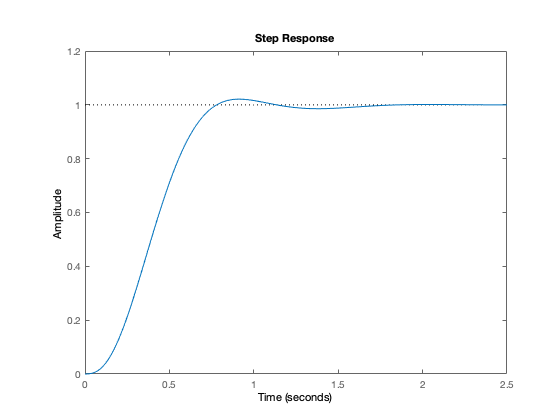

step (sys)

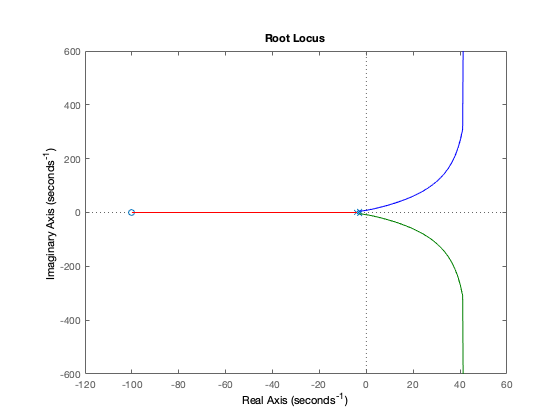

rlocus(sys)

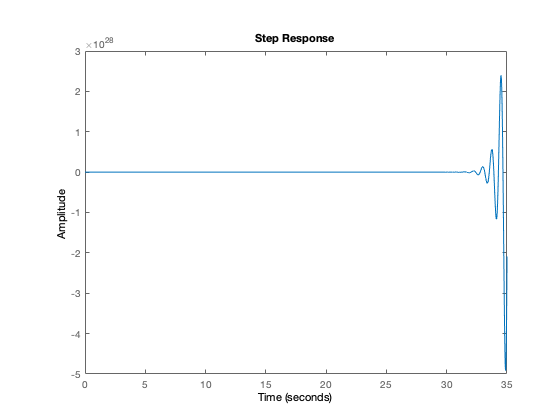


k1 = 1;
k2 = 1;
sys = (k1 * (s+100))/(0.1*s^3+ s^2 + (k1+k2)*s + 100*k1) ;
step (sys)